# **Analytic Performance Estimator**

**Summary:**

This program summarizes most of my work on the small KID's project. In here the most of the quasi analytical model that i use to predict/estimate performance of cetain set of parameters. 

## Physical constants:

%-Useful Physics constants
phyconst.c = 299792458 ;% [m/s] - Speed of light! 
phyconst.epsilon0 = 8.854187E-12;% [C/m]
phyconst.mu0 = 1/(phyconst.epsilon0*(phyconst.c^2)) % [s/(C*m) = Henry/m]

phyconst = struct with fields:
           c: 299792458
    epsilon0: 8.854187000000001e-12
         mu0: 1.256637177477298e-06
           h: 6.626000000000000e-34
          kb: 1.380000000000000e-23
           e: 1.602000000000000e-19


phyconst.h = 6.626E-34 % [J*s]

phyconst = struct with fields:
           c: 299792458
    epsilon0: 8.854187000000001e-12
         mu0: 1.256637177477298e-06
           h: 6.626000000000000e-34
          kb: 1.380000000000000e-23
           e: 1.602000000000000e-19


phyconst.kb = 1.38E-23 % [J/K]

phyconst = struct with fields:
           c: 299792458
    epsilon0: 8.854187000000001e-12
         mu0: 1.256637177477298e-06
           h: 6.626000000000000e-34
          kb: 1.380000000000000e-23
           e: 1.602000000000000e-19


phyconst.e  = 1.602E-19 % [Coulomb]

phyconst = struct with fields:
           c: 299792458
    epsilon0: 8.854187000000001e-12
         mu0: 1.256637177477298e-06
           h: 6.626000000000000e-34
          kb: 1.380000000000000e-23
           e: 1.602000000000000e-19


## Setup

%% Setup
%clc
close all 
%clear
tic
%clear all %clear classes % Increasingly strong statements about clearing
%everything
% Parameters
Z0 = 79.605;%[Ohm] --> value from CPW simulation sonnet. varies only slightly as function of freq <0.1%
Z0_PEC =65.3696 ;%%[Ohm] --> value from CPW simulation sonnet. varies only slightly as function of freq <3ppm
epsilon_eff = 10.6008;%[-] --> value from CPW simulation sonnet. varies only slightly as function of freq <0.1%
epsilon_eff_PEC = 7.1484;%[-] --> value from CPW simulation sonnet. varies only slightly as function of freq <0.1%
epsilon0 = 8.854187E-12;% [C/m]
length_M = 0.001;%[m]
d = 250E-9;%[m]


### Sonnet simulation 

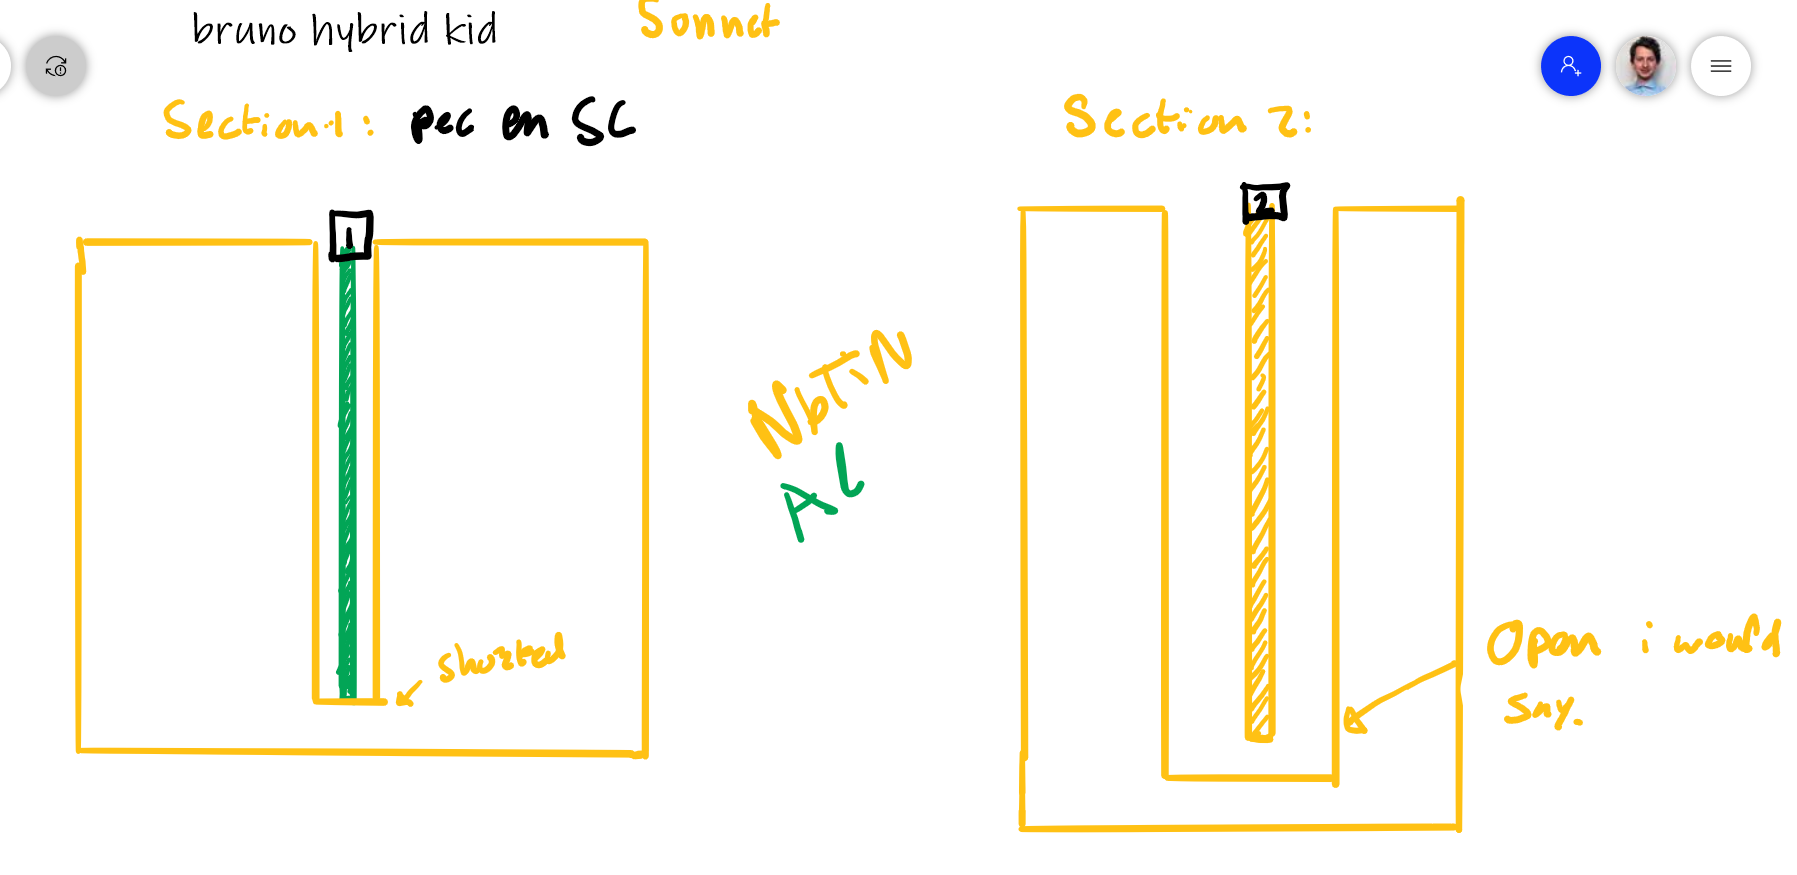



%Data path
addpath('.\Sonnet_data')
filename_begin = 'PPCV0_9_9A2114.csv';%Bruno Adapt: add section 2 here 
%filename_end = '.csv';
filename_CPW_SC = 'AlHybridV0_0_3_SC.csv';%Bruno Adapt: add section 1 here Superconducting version
filename_CPW_PEC = 'AlHybridV0_0_3_PEC.csv';%Bruno Adapt: add section 1 here Perfect Electrical conductor(PEC) version
%Extended with (1-1-1) and (0.5-0.5-0.5) CPW.
filename_CPW_SC1 = 'AlHybridV0_0_3_SC.csv';
filename_CPW_PEC1 = 'AlHybridV0_0_3_PEC.csv';
filename_CPW_SC0_5 = 'AlHybridV0_0_3_SC.csv';
filename_CPW_PEC0_5 = 'AlHybridV0_0_3_PEC.csv';



## Loading data and making objects

Lorem ipsum dolor sit amet, consectetur adipiscing elit. Quisque sed mi  mauris. Duis scelerisque, mauris a ultricies luctus, felis enim molestie ligula, ultricies sagittis magna sapien quis magna. Curabitur velit  enim, porttitor sed odio vel, vehicula hendrerit purus. Morbi ultricies  ipsum quis nisi porttitor, in sollicitudin tortor commodo. Nulla  facilisi. Donec sed laoreet lacus. Integer ornare semper metus tristique aliquet. Nunc tristique mi ex, et rutrum mauris lacinia ac. 

%% Loading Data and making objects.

A_filename_umsquared = [12710,10056,8320,7094,6184,5480,4920,4464,4086,3766,3493,3257,3051,2869,2708,2564,2434,2317,2211,2114];
A_ppc = A_filename_umsquared.*((1E-6)^2);

%5Target Toy model data validation
F0_5Target = [5.86083 5.5316 5.33138 4.72955 4.01304 3.10839].*10^9;% Old data
PPC_To_be_squared = [47.0213 50 52.0384 59.1016 70.1727 91.214].*10^(-6);% Old data
A_ppc_5Target = PPC_To_be_squared.*PPC_To_be_squared;

F0_5TargetV2 = [3.9788 5.2523 5.44361 5.7568 8.64393].*10^9;% New data
PPC_To_be_squaredV2 = [70 52 50 47 29].*10^(-6);% New data
A_ppc_5TargetV2 = PPC_To_be_squaredV2.*PPC_To_be_squaredV2;

% Jochem Code data
F0_Jochem = [2310621857.66901,2594151197.17164,2848091619.57189,3080193995.21574,3294570175.75902,3495048293.57827,3683595761.38946,3861932630.02850,4031177778.48288,4193284041.57368,4348211285.19556,4496947156.08466,4640060715.25595,4778557898.03422,4911996912.86868,5041319369.84867,5167282193.70940,5289103153.16627,5407241595.85572,5522580077.27439];
A_ppc;



%Bruno Adapt%iterator = 1:length(A_ppc);
iterator = 1:1

iterator =      1


%Constructs the PPC theory  and PPC sonnet objects.
PPCt = repmat(PPC_theory(),1,length(iterator));% convoluded way of preallocating an array of the objects
PPCs = repmat(PPC_sonnet_oneport(),1,length(iterator));% convoluded way of preallocating an array of the objects
for i=iterator
    %Constructor arg: PPC_theory(W (Width PPC(m)),H (Lenght PPC(m)),d (thickness dielectric(m)),e_r(number))
    PPCt(i) = PPC_theory(sqrt(A_ppc(i)),sqrt(A_ppc(i)),250E-9,10);
    total_filename = filename_begin;
    % PPC_sonnet_oneport(Width(m),N Length(m),d thickness(m),data_dir)
    PPCs(i) = PPC_sonnet_oneport(sqrt(A_ppc(i)),sqrt(A_ppc(i)),250E-9,total_filename,9);
end
% Constructs the CPW objects.
CPWtSC = CPW_theory(length_M,Z0,epsilon_eff);
CPWtPEC = CPW_theory(length_M,Z0_PEC,epsilon_eff_PEC);
CPWsSC = CPW_sonnet_oneport(2E-6,2E-6,length_M,filename_CPW_SC,9);
CPWsPEC = CPW_sonnet_oneport(2E-6,2E-6,length_M,filename_CPW_PEC,9);

CPWsSC1 = CPW_sonnet_oneport(1E-6,1E-6,length_M,filename_CPW_SC1,9);
CPWsPEC1 = CPW_sonnet_oneport(1E-6,1E-6,length_M,filename_CPW_PEC1,9);
CPWsSC0_5 = CPW_sonnet_oneport(0.5E-6,0.5E-6,length_M,filename_CPW_SC0_5,9);
CPWsPEC0_5 = CPW_sonnet_oneport(0.5E-6,0.5E-6,length_M,filename_CPW_PEC0_5,9);



## Analysis: Finding intersectes Im[Z_{cpw}] = -Im[Z_{PPC}]

Lorem ipsum dolor sit amet, consectetur adipiscing elit. Quisque sed mi  mauris. Duis scelerisque, mauris a ultricies luctus, felis enim molestie ligula, ultricies sagittis magna sapien quis magna. Curabitur velit  enim, porttitor sed odio vel, vehicula hendrerit purus. Morbi ultricies  ipsum quis nisi porttitor, in sollicitudin tortor commodo. Nulla  facilisi. Donec sed laoreet lacus. Integer ornare semper metus tristique aliquet. Nunc tristique mi ex, et rutrum mauris lacinia ac. 

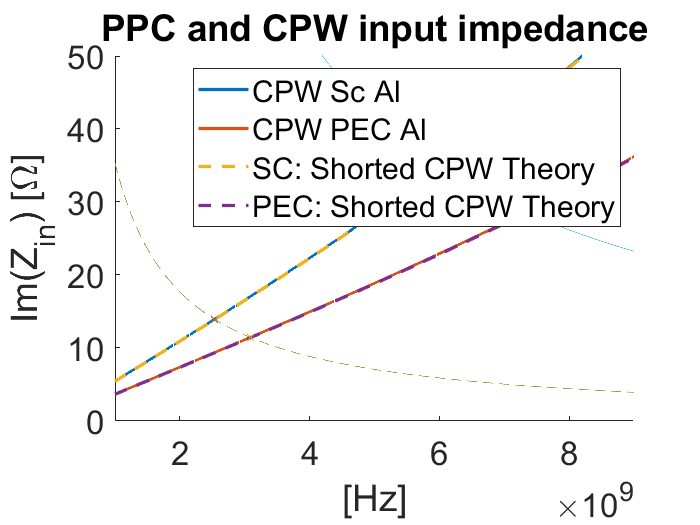

%% Analyse data. Finding the intersects between CPW and PPC curves.
%Disp graph for the input impedance 
freq = PPCs.get_freq();
f1 = figure;
hold on
hcpwsc = sweetplot(CPWsSC.get_freq(),imag(CPWsSC.get_Zin));
hcpwpec = sweetplot(CPWsPEC.get_freq(),imag(CPWsPEC.get_Zin));
hcpwt = plot(freq,imag(CPWtSC.get_Zin(freq)),'--','linewidth',2);
hcpwt_PEC = plot(freq,imag(CPWtPEC.get_Zin(freq)),'--','linewidth',2);
plot_iterator = iterator;
for i=plot_iterator
    ht(i) = plot(freq,-imag(PPCt(i).get_Zin(freq)),'--');
    hts(i) = plot(freq,-imag(PPCs(i).get_Zin()));
    [x_intersect_sc(i),y_intersect_sc(i)] = find_intersect_2lines(PPCs(i).get_freq(),CPWsSC.get_freq(),-imag(PPCs(i).get_Zin()),imag(CPWsSC.get_Zin()),'linearinterp',0);
    [x_intersect_pec(i),y_intersect_pec(i)] = find_intersect_2lines(PPCs(i).get_freq(),CPWsPEC.get_freq(),-imag(PPCs(i).get_Zin()),imag(CPWsPEC.get_Zin()),'linearinterp',0);
    [x_intersect_sc_t(i),y_intersect_sc_t(i)] = find_intersect_2lines(freq,freq,-imag(PPCt(i).get_Zin(freq)),imag(CPWtSC.get_Zin(freq)),'linearinterp',0);
    [x_intersect_pec_t(i),y_intersect_pec_t(i)] = find_intersect_2lines(freq,freq,-imag(PPCt(i).get_Zin(freq)),imag(CPWtPEC.get_Zin(freq)),'linearinterp',0);
    %normalizedtextarrow(gca(),[8.9E9 -imag(PPCs(i).get_Zin(4000))],[(freq(4000)) -imag(PPCs(i).get_Zin(4000))],string(PPCs(i).get_W()*1E6*50))
    set(gca,'FontSize',20);
end
hisc = plot(x_intersect_sc(plot_iterator),y_intersect_sc(plot_iterator),'o');
hipec = plot(x_intersect_pec(plot_iterator),y_intersect_pec(plot_iterator),'o');
hitsc = plot(x_intersect_sc_t(plot_iterator),y_intersect_sc_t(plot_iterator),'x');
hitpec = plot(x_intersect_pec_t(plot_iterator),y_intersect_pec_t(plot_iterator),'x');



xlabel('[Hz]')
ylabel('Im(Z_{in}) [\Omega]')
title('PPC and CPW input impedance')
xlim([1E9 9E9]);
ylim([0 50]); 
%Bruno Adapt%normalizedtextarrow(gca(),[(freq(3000)-1E9) -imag(PPCt(15).get_Zin(freq(3000)))],[(freq(3000)) -imag(PPCt(15).get_Zin(freq(3000)))],'Theory')% This needs some shaving to get at the right place!
%Bruno Adapt%normalizedtextarrow(gca(),[(freq(3400)-1E9) -imag(PPCs(15).get_Zin(3400))],[(freq(3400)) -imag(PPCs(15).get_Zin(3400))],'Sonnet PPC')
legend([hcpwsc hcpwpec hcpwt hcpwt_PEC],{'CPW Sc Al','CPW PEC Al','SC: Shorted CPW Theory','PEC: Shorted CPW Theory'});
hold off

## Calculation of the deltaF_0

Lorem ipsum dolor sit amet, consectetur adipiscing elit. Quisque sed mi  mauris. Duis scelerisque, mauris a ultricies luctus, felis enim molestie ligula, ultricies sagittis magna sapien quis magna. Curabitur velit  enim, porttitor sed odio vel, vehicula hendrerit purus. Morbi ultricies  ipsum quis nisi porttitor, in sollicitudin tortor commodo. Nulla  facilisi. Donec sed laoreet lacus. Integer ornare semper metus tristique aliquet. Nunc tristique mi ex, et rutrum mauris lacinia ac. 

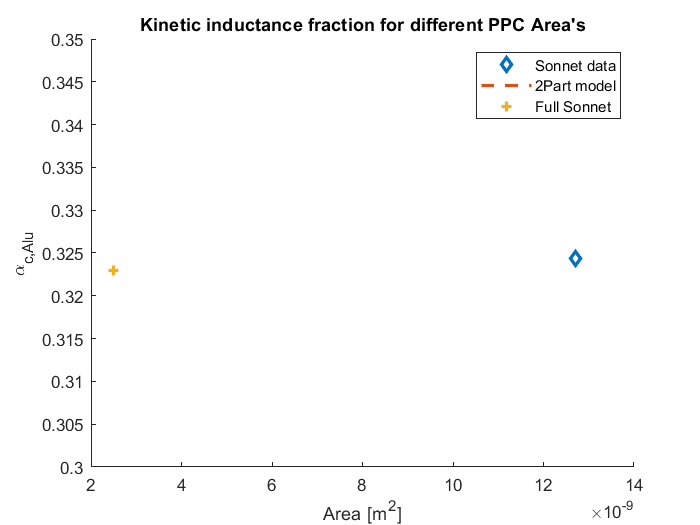

%% Calculation of the deltaF_0
iterator_partial = iterator;
alpha_c_alu =  kindfrac(x_intersect_sc,x_intersect_pec);
alpha_c_alu_t =  kindfrac(x_intersect_sc_t,x_intersect_pec_t);
%Now we add 1 point of data for the Toy_Model Origin2500 and Origin2500PEC
% In order to get 1 data Point.
alpha_c_alu_Origin2500 = kindfrac(5.5316,6.72285);



f2 = figure;
hold on 
sizes_W = arrayfun( @(x) x.get_W, PPCs  );
sizes_H = arrayfun( @(x) x.get_H, PPCs );
sizes_A = sizes_W(iterator_partial).*sizes_H(iterator_partial);
sizes_W_t = arrayfun( @(x) x.get_W, PPCt  );
sizes_H_t = arrayfun( @(x) x.get_H, PPCt );
sizes_A_t = sizes_W_t(iterator_partial).*sizes_H_t(iterator_partial);
%Bruno Adapt%plot(sizes_A,alpha_c_alu(iterator_partial),'LineWidth',2);
plot(sizes_A,alpha_c_alu(iterator_partial),'d','LineWidth',2);
plot(sizes_A_t,alpha_c_alu_t(iterator_partial),'--','LineWidth',2);
plot(2500E-12,alpha_c_alu_Origin2500,'+','LineWidth',2);
title("Kinetic inductance fraction for different PPC Area's")
ylim([0.3 0.35])
legend('Sonnet data','2Part model','Full Sonnet')
xlabel('Area [m^{2}]')
ylabel('\alpha_{c,Alu}')
hold off

%ylim([0 0.2])



## Bruno: Output alpha_k , F0(SC), F0(PEC)

Hi Bruno! Here is the output of the program that you want to have 

fprintf("alpha_k = ");disp(alpha_c_alu(1))

alpha_k =    0.324411154008882



fprintf("F0_SC = ");disp(x_intersect_sc(1));

F0_SC =      6.026816266215138e+09



fprintf("F0_PEC = ");disp(x_intersect_pec(1));

F0_PEC =      7.332409583762506e+09



## Fitting in Log-log space

Lorem ipsum dolor sit amet, consectetur adipiscing elit. Quisque sed mi  mauris. Duis scelerisque, mauris a ultricies luctus, felis enim molestie ligula, ultricies sagittis magna sapien quis magna. Curabitur velit  enim, porttitor sed odio vel, vehicula hendrerit purus. Morbi ultricies  ipsum quis nisi porttitor, in sollicitudin tortor commodo. Nulla  facilisi. Donec sed laoreet lacus. Integer ornare semper metus tristique aliquet. Nunc tristique mi ex, et rutrum mauris lacinia ac. 

%% fitting F0=C*A^k by fitting in log log space.
sizes_A = sizes_W(plot_iterator).*sizes_H(plot_iterator);
[f5,hpower, a , b , str_formula] = powerlaw_fit(sizes_A,x_intersect_sc(plot_iterator));

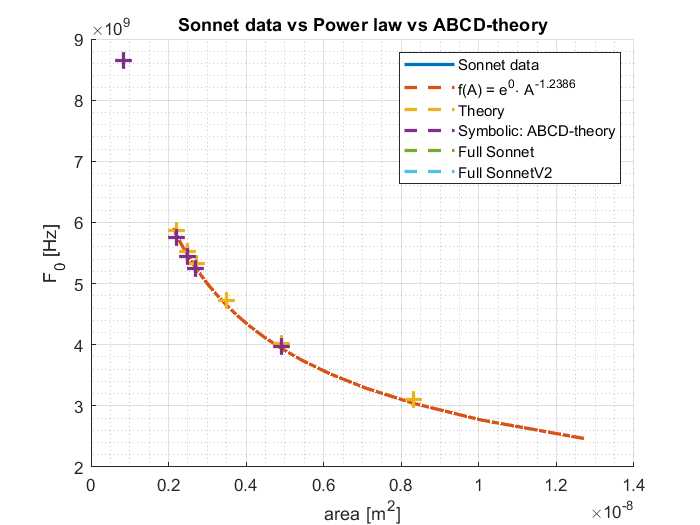

figure(f5)
conv_iter = 1:10;% this makes sure the theory is run 10 times to make it converge to the actual value.
f_start =1E9;
f = f_start;

%F0_out =  zeros(length(iterator));
F0 = zeros(length(conv_iter));
for j=iterator
    for i=conv_iter
    F0(i) = F0_theory(f,0.001,A_ppc(j),Z0,epsilon_eff,d);%F0 = F0_theory(freq[Hz],lenght_CPW[m],AreaPPC[m^2],Z0[Ohm],epsilon_eff[-],d[m])
    err = (F0(i)-f)./F0(i);
    f = (F0(i)+f)/2;% in this piece of the code  we make a new guess using the formula averaged with the previous guess in order to converge into the final value.
    end
F0_out(j) = F0(length(conv_iter));
end
hold on
plot(sizes_A,x_intersect_sc_t,'--','linewidth',2);
plot(A_ppc,F0_out,'-.','linewidth',2)
h5Target = plot(A_ppc_5Target,F0_5Target,'+');
h5Target.MarkerSize = 10;
h5Target.LineWidth = 2;
h5TargetV2 = plot(A_ppc_5TargetV2,F0_5TargetV2,'+');
h5TargetV2.MarkerSize = 10;
h5TargetV2.LineWidth = 2;
%hJochem = plot(A_ppc,F0_Jochem);
%hJochem.MarkerSize = 10;
%hJochem.LineWidth = 2;
legend('Sonnet data',str_formula,'Theory','Symbolic: ABCD-theory','Full Sonnet','Full SonnetV2');
title('Sonnet data vs Power law vs ABCD-theory');
grid on 
grid minor
hold off

## Relation between Qc and A_coupler 

In here i am now attempting to find the relation between the coupling strength expressed in the Qc of the resonator. And the overlap area beween the coupler and the readout line. 

I already suspect that a large ovelap corresponds to a Low Qc. and a large overlap corresponds to a High Qc. But the relationship exact at this moment remains unknown. 

*Work in progress!*

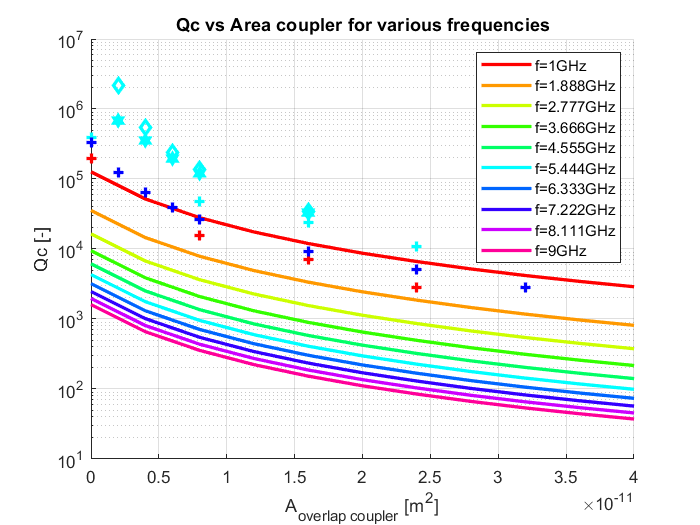

%% Relation between Qc and A_coupler 
%g(A_coupler) =  Q_coupler
% UNIT_Coupler_sonnet_class();
%Making objects for the Coupler data
filename_coupler = 'Coupler_FullDielectricV0_5_0Oeff';
iterator_coupler = 1:20;
%CAUTION: i have added the x=2.554 correction factor that has been
%calcuated from the discussion on mail with Alejandro Akira. See
%Dropbox>MEP>Milestone 1>Markdown>Couplers.md or Couplers.html or Obsidian
% - Couplers = Rani formula + Alegandro correction.

for i=iterator_coupler
    Couplers(i) = Coupler_sonnet(4E-6,(i-1)*10^(-6),250E-9,0.05585,filename_coupler+string(i)+filename_end,15);
end
% Number of header lines 15
%Plotting the coupler data for 1 freq.
figure
ax = axes('XScale', 'linear', 'YScale', 'log');
Coupler_Freq_steps = 10;
ax.ColorOrder = hsv(Coupler_Freq_steps);
hold on 
%Data from lorenzian fit 
O_coupler_eff = [0 2 4 6]*10^-6;
A_coupler_eff = O_coupler_eff.*4E-6;
Lor_Area = A_coupler_eff;
O_coupler_eff3 = [0 0.5 1 1.5 2 4 6 8]*10^-6;
A_coupler_eff3 = O_coupler_eff3.*4E-6;
Lor_Area3 = A_coupler_eff3;
Lor_Qc = [396889.6308827559 47833.89909514129 23705.915491265154 10976.09187079];
Lor_Qc2 = [195844 15822 6986 2774];
Lor_Qc3 = [334080 123384 64291 39194 25999 9360 5051 2816];

% Data from ADS
O_coupler_eff_ADS = [0.5 1 1.5 2 4 8]*10^-6;
A_coupler_eff_ADS = O_coupler_eff_ADS.*4E-6;
Lor_Qc_ADS = [2.17E6 550.46E3 243E3 136.9E3 34.3E3 8655];
Lor_Qi_Assumed_ADS = [1E6 1E6 1E6 1E6 1E6 1E6 ];
for i=1:length(Lor_Qi_Assumed_ADS)
Lor_Q_ADS(i) = calcQadd(Lor_Qi_Assumed_ADS(i),Lor_Qc_ADS(i));
end
for i=1:Coupler_Freq_steps
freq_index = floor(subsref(linspace(1,8001,Coupler_Freq_steps),struct('type','()','subs',{{i}})));%Matlab ugly way of doing inline indexing linspace is input and {} is the index
Area_Couplers = arrayfun( @(x) x.get_Area, Couplers  );
Qc_Couplers = arrayfun( @(x) x.get_Qc(freq_index), Couplers );
plot(Area_Couplers,Qc_Couplers,'LineWidth',2);
LegendData{i}='f='+string(Couplers(1).get_freq(freq_index)/10^9)+'GHz' ;
end
plot(Lor_Area, Lor_Qc,'+','Linewidth',2,'Color','c')
plot(Lor_Area, Lor_Qc2,'+','Linewidth',2,'Color','r')
plot(Lor_Area3, Lor_Qc3,'+','Linewidth',2,'Color','b')
plot(A_coupler_eff_ADS, Lor_Qc_ADS,'d','Linewidth',2,'Color','c')
plot(A_coupler_eff_ADS, Lor_Q_ADS,'h','Linewidth',2,'Color','c')
hold off
grid on
xlabel('A_{overlap coupler} [m^{2}]')
ylabel('Qc [-]')
xlim([0 4E-11])
legend(LegendData)
title('Qc vs Area coupler for various frequencies')
saveas(gcf,'.\Images\Auto_QcArea','svg')
saveas(gcf,'.\Images\Auto_QcArea','pdf')

### Define function that contains this whole graph...

---> Make!!!

## Make parameters for 16 CKIDs

Over here I calculate the area for 16 equally spaced CKIDs. Already talked to Jochem and probably we want to make 3 groups of 4 KIDs that are in quite a small piece of spectrum.


%% Make parameters for 16 CKIDs

% Linspace between 4-8 GHz of 16 CKIDs
addpath('.\Exportdata')
F0_16CKID = linspace(4,8,16);
%Use struct to refactor code over here.
Area_16CKID = f_inv_fit(a,b,F0_16CKID,'native')';

CKID_DataPackage= [F0_16CKID' Area_16CKID ];
writematrix(CKID_DataPackage,'Exportdata/Datapackage.csv','Delimiter','tab')



## Get responsivity

%% Calc. parameters responsivity. Get responsivity.
% In here i want to calculate the parameters to calculate the responsivity.


### Intermezzo:Mazin naive formula 

i found a formula for 6 GHz resonator in his dissertation. So my responsivity has to be in the ballpark range of this formula.

Guesstimations about responsivity compared to DESHIMA 2.0

V~ same 

Q~ same

Kin.ind.fraction ~ 0.32 which is approx 6x as high


$$\frac{d\theta}{dN_{qp}}=1.63\cdot10^{-7} \frac{\alpha_k Q}{V}$$


(Source: Mazin Dissertation p.33)

**Compare to slide of SAI:**

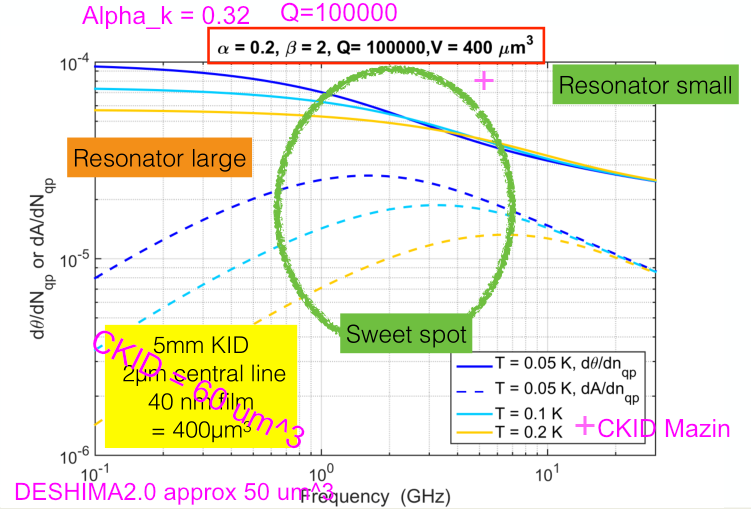

(Source: Slides Superconduting astronomical instumentation )

And Jochem code:


$$\frac{dA}{dN_{qp}} = -2.66\cdot 10^{-5}$$



$$\frac{d\theta}{dN_{qp} }= 7.23\cdot 10^{-5}$$


% Start-----Compare Mazin 
CKID.Qi = 2E6;
CKID.Qc = 100000;
CKID.Q = (CKID.Qi*CKID.Qc)/(CKID.Qi + CKID.Qc);
Alu.length = 1000; %[um] (Me: Also in m in Jochem code)
Alu.width = 2; %[um] (Me)
Alu.height = 0.030; %[um](Me)
Alu.V = Alu.length*Alu.width*Alu.height ; %[um^3] (Me)(Checked)
CKID.phaseresponsivity = dphaseMazin(0.32,CKID.Q,Alu.V)

CKID = struct with fields:
                   Qi: 2000000
                   Qc: 100000
                    Q: 9.523809523809524e+04
    phaseresponsivity: 8.279365079365079e-05




disp('dthetadNqp Mazin = '+string(CKID.phaseresponsivity));

dthetadNqp Mazin = 8.2794e-05


% End ------Compare Mazin


### End intermezzo

## Stitching Jochem code: Obtaining resposivity

Temp = [ 0.2 0.1 0.05];
for j=1:length(Temp)
%Parameters necessary for getNqp_Tbath function.
Alu.Teff = 0.05; % [K] (Source: Jochem code)(Checked) 
Alu.Tc          = 1.125;    % [K] (Source: Jochem code)(Checked)
Alu.eta_pb      = 0.4;      % (Source: Jochem code)(Checked)pair breaking eficiency 0.4 for medium thin aluminium on Si, 0.56 for thick Alu
Alu.tau0        = 4.38e-7;   % (Source: Jochem code)(Checked)Kaplan single particle tau_0. 438e-9 is the Kaplan value. Can change and our old papers have a factor wrong here
KID.Tbath = 0.05 ; % [K] (Source: Jochem code)

%---> Begin global constants from Jochem code:
global hbar kb e_c c mu0 eps0 N0 vf ksi0 lambda0 tau0;%in SI units
% constants
e_c=1.602e-19;          %single electron charge in C
kb=1.3806503e-23;       %boltzmann contstant J/K
hbar=6.60607e-34/2/pi;  %1.054571e-34;  %reduced plancks constant
mu0=4*pi*1e-7;          %Permeability of vacuum
eps0=8.8541878e-12;       %delectric consant of vacuum 
c=2.99792e8;               %speed of light
tau0=458e-9;                %in sec. from PRL PdV
%%%%%%%%%%%% fixed parameters alumninium %%%%%%%%%%%%
N0 = 1.72e10/e_c;             %density of states in /J/um^3
vf = 2.03e6;                  %Fermi Velocity m
ksi0 = 1.6e-6;        %coherence length bulk m
lambda0 = 16e-9;      %penetration depth bulk m
%---> End global constants Jochem code.




sigma_n_Al = 3.77E7; % [Siemens/m] Source: https://en.wikipedia.org/wiki/Electrical_resistivity_and_conductivity

[Alu.nqp, Alu.tauqp, Alu.Nqp, KID.NEPGR] = getNqp_Tbath(Alu.Tc, Alu.eta_pb, Alu.V, KID.Tbath, Alu.tau0);% Jochem


Alu.l_elec = 5.838E-9; % (Source Jochem code) Jochem says beta is electron mean free path. Strange but ok!
KID.alphatot = alpha_c_alu_Origin2500;%(Me)
KID.Qc = 100000;%(Me)
Alu.t = 30e-9; %(Me)
Qim = 2000000;%(Me, For now this is a guess)
Alu.N0   =1.0737E29  ;% (Source: Jochem code)
Alu.Delta= 0.1706 ;% (Source: Jochem code )
Alu.Teff =0.150; % [K](Source: Jochem code)
KID.Fres = linspace(1E9,9E9,100);%(Me)
for i=1:length(KID.Fres)
%beta = calcbeta(KID.Fres(i),epsilon_eff,phyconst.c);
[Alu.sigma1,Alu.sigma2,Alu.ds1dn,Alu.ds2dn]= Sigmas(2*pi*KID.Fres(i), Alu.N0, Alu.Delta, Alu.Teff);      %MB equations, vaklkid for T<<Tc, F<<Fgap
[KID.dthetadN,KID.dAdN,KID.dxdN,Alu.abssigma,KID.Qi,KID.Q,Alu.Beta]= getresponsivity2(Alu.l_elec,KID.alphatot,KID.Qc,Alu.V,Alu.sigma1,Alu.sigma2,Alu.ds1dn,Alu.ds2dn,Alu.t,Qim);
Jout_dthetadN(i,j) = (Alu.V./(KID.alphatot.*KID.Qc)).*KID.dthetadN;
Jout_dAdN(i,j) = (Alu.V./(KID.alphatot.*KID.Qc)).*KID.dAdN;
end 
end                    
% Plotting of this obtained data:
 
f3 = figure

f3 =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.940000000000000 0.940000000000000 0.940000000000000]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


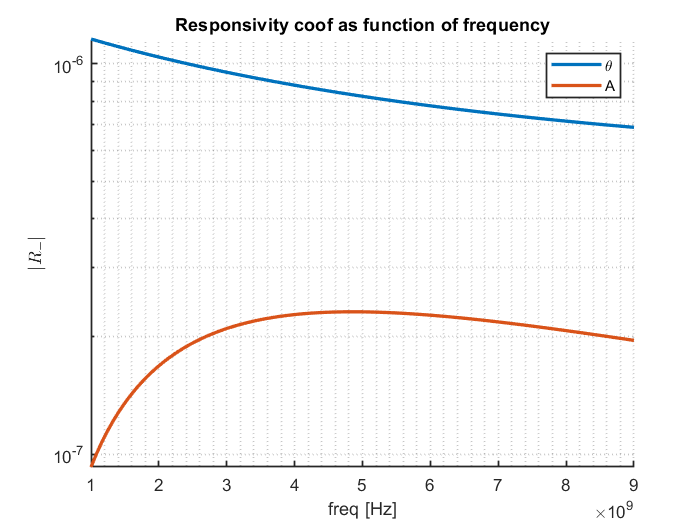

ax = axes('XScale', 'linear', 'YScale', 'log');
hold on
for j=1:1
plot(KID.Fres,Jout_dthetadN(:,j),'linewidth',2)
plot(KID.Fres,abs(Jout_dAdN(:,j)),'linewidth',2)%Caution: took the absolute value to make it work on log scale
end
hold off
title('Responsivity coof as function of frequency')
xlabel('freq [Hz]')
ylabel('$|R_{-}|$','Interpreter','latex' )
legend('\theta','A')
% '\frac{}{dN_{qp}}'
grid minor
set(gca,'linewidth',1)



                                                  %[dthetadN,dRdN,dxdN,abssigma,Qi,Q,Beta] = getresponsivity2(length,alphak,Qc,V,sigma1,sigma2,ds1dn,ds2dn,d,Qim)
%Display the found responsivity and sigmas
disp('dthetadN = '+string(KID.dthetadN)+'\n');

dthetadN = 0.00036951\n


disp('dAdN = '+string(KID.dAdN)+'\n');

dAdN = -0.0001052\n


## Noise: PSD plots papers

The goal of this section is to visualize the PSD of the different noise sources found in the following papers:

### Paper 5: 

Here is a slider for 


$$P={10}^x$$


typical values range from 

fW: x=

p5_x= -15;
p5_P_sky = 10^p5_x;
p5_freq_sky = linspace(220E9,440E9,1000);
p5_NEP_photon = zeros(1,length(p5_freq_sky));
p5_NEP_gr = zeros(1,length(p5_freq_sky));

In slides SAI:


$$\Delta = 1.76 k_{B}T_c$$


And in (Thoen, 2016, Superconducting NbTiN Thin Films... )

Tc,NbTiN = 15K - 15.3K

Tc,Al = 1.28K

p5_TcNbTiN = 15.15;
p5_TcAl = 1.28

p5_TcAl =    1.280000000000000


p5_Delta = (1.76*phyconst.kb*p5_TcAl);
p5_etapb = 0.6;
for i=1:length(p5_freq_sky)
p5_NEP_photon(i) = sqrt(2*p5_P_sky*phyconst.h*p5_freq_sky(i));
p5_NEP_gr(i)  = sqrt((2*p5_P_sky*p5_Delta)/p5_etapb);
end
f4 = figure

f4 =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.940000000000000 0.940000000000000 0.940000000000000]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


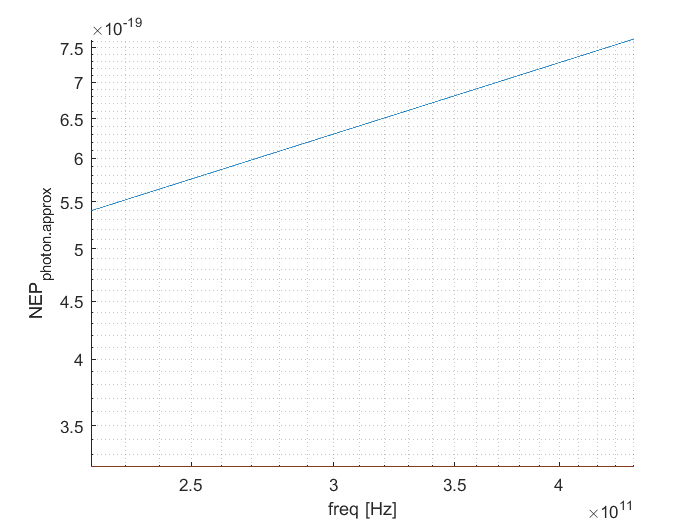

ax2 = axes('XScale', 'log', 'YScale', 'log');
hold on 
plot(p5_freq_sky,p5_NEP_photon)
plot(p5_freq_sky,p5_NEP_gr)

xlabel('freq [Hz]')
ylabel('NEP_{photon.approx}')
grid minor
hold off

# Appendix

Additional programs that can come in handy(You don't need to run these.)